# Performing Group Calculations

It is time to perform group calculations on the blue whale data.

load cleanWhaleData.mat
whales

whales = 14514×8 table
           ID                  timestamp           longitude    latitude    sensorQuality    sensorMeasurements        sensorType         markedOutliers
    ________________    _______________________    _________    ________    _____________    __________________    ___________________    ______________

    1993CA-Bmu-00834    1993-08-29 01:23:17.000     -122.41      36.981           1                  4             argos-doppler-shift          ""      
    1993CA-Bmu-00834    1993-08-31 13:04:34.000     -122.79      37.637           B                  2             argos-doppler-shift          ""      
    1993CA-Bmu-00834    1993-09-01 01:57:39.000     -122.83      37.166           B         

% Compute group summary
newTable2 = groupsummary(whales,"ID","range","latitude");
newTable2.GroupCount = []

newTable2 = 140×2 table
           ID           range_latitude
    ________________    ______________

    1993CA-Bmu-00834        0.656     
    1993CA-Bmu-10823            0     
    1993CA-Bmu-10836        0.551     
    1994CA-Bmu-00848        0.579     
    1994CA-Bmu-10820        0.913     
    1994CA-Bmu-10821            0     
    1994CA-Bmu-10822            0     
    1994CA-Bmu-10823        1.598     
    1994CA-Bmu-10824        0.045     
    1994CA-Bmu-10828        6.839     
    1994CA-Bmu-10829        0.454     
    1994CA-Bmu-23029        0.168     
    1995CA-Bmu-00837        1.789     
    1995CA-Bmu-00841        0.882     
    1995CA-Bmu-00845        2.404     
    1995CA-Bmu-02082        0.825     


newTable2 = sortrows(newTable2, "range_latitude", "descend")

newTable2 = 140×2 table
           ID           range_latitude
    ________________    ______________

    2008CA-Bmu-04176        34.652    
    2007CA-Bmu-01385        34.495    
    2005CA-Bmu-10821        33.208    
    2000CA-Bmu-01386        31.687    
    2000CA-Bmu-01390         30.58    
    2004CA-Bmu-04175        29.387    
    2005CA-Bmu-01390        28.747    
    2005CA-Bmu-10829        28.647    
    2000CA-Bmu-10828        28.432    
    2006CA-Bmu-02083        27.998    
    1998CA-Bmu-10823        27.936    
    1999CA-Bmu-04172        27.396    
    2000CA-Bmu-10832        26.931    
    2007CA-Bmu-23043        25.964    
    2007CA-Bmu-05801        25.841    
    2006CA-Bmu-10840        24.987    


whaleSummary = newTable2

whaleSummary = 140×2 table
           ID           range_latitude
    ________________    ______________

    2008CA-Bmu-04176        34.652    
    2007CA-Bmu-01385        34.495    
    2005CA-Bmu-10821        33.208    
    2000CA-Bmu-01386        31.687    
    2000CA-Bmu-01390         30.58    
    2004CA-Bmu-04175        29.387    
    2005CA-Bmu-01390        28.747    
    2005CA-Bmu-10829        28.647    
    2000CA-Bmu-10828        28.432    
    2006CA-Bmu-02083        27.998    
    1998CA-Bmu-10823        27.936    
    1999CA-Bmu-04172        27.396    
    2000CA-Bmu-10832        26.931    
    2007CA-Bmu-23043        25.964    
    2007CA-Bmu-05801        25.841    
    2006CA-Bmu-10840        24.987    


topID = whaleSummary.ID(1)

topID = categorical
     2008CA-Bmu-04176 


rowsToKeep= whales.ID == topID

rowsToKeep = 14514×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


topWhale = whales(rowsToKeep,:)

topWhale = 259×8 table
           ID                  timestamp           longitude    latitude    sensorQuality    sensorMeasurements        sensorType         markedOutliers
    ________________    _______________________    _________    ________    _____________    __________________    ___________________    ______________

    2008CA-Bmu-04176    2008-07-28 00:40:25.000     -120.04      34.134           0                   5            argos-doppler-shift          ""      
    2008CA-Bmu-04176    2008-07-28 21:24:11.000     -120.61      34.115           0                   4            argos-doppler-shift          ""      
    2008CA-Bmu-04176    2008-07-29 21:11:49.000     -119.15      33.277           A         

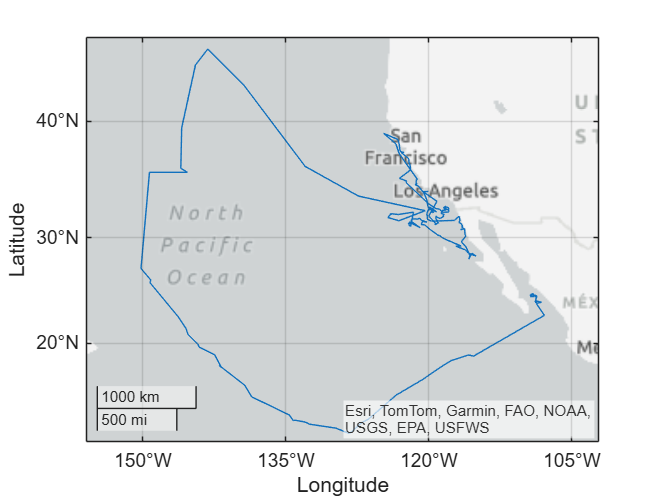


geoplot(topWhale.latitude,topWhale.longitude)